# ME-8930 | LMIs for Robust & Optimal Control Design

## Capstone Project

**Team:** Chinmay Samak and Tanmay Samak

clear;
close;
clc;

% Environment parameters

u_fl = 0.4; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.4; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.4; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.4; % Coefficient of friction for ground and RR tire interconnect

% Vehicle parameters

m = 2.68; % Mass [kg]
J = 0.01944; % Yaw moment of inertia [kg-m^2]
l = 0.1415; % Wheelbase [m]
l_f = 0.49*l; % Distance from CG to front axel [m]
l_r = l-l_f; % Distance from CG to rear axel [m]
C_fl = 2.4768; % Cornering stiffness of FL tire [N/rad]
C_fr = 2.4768; % Cornering stiffness of FR tire [N/rad]
C_rl = 2.4768; % Cornering stiffness of RL tire [N/rad]
C_rr = 2.4768; % Cornering stiffness of RR tire [N/rad]

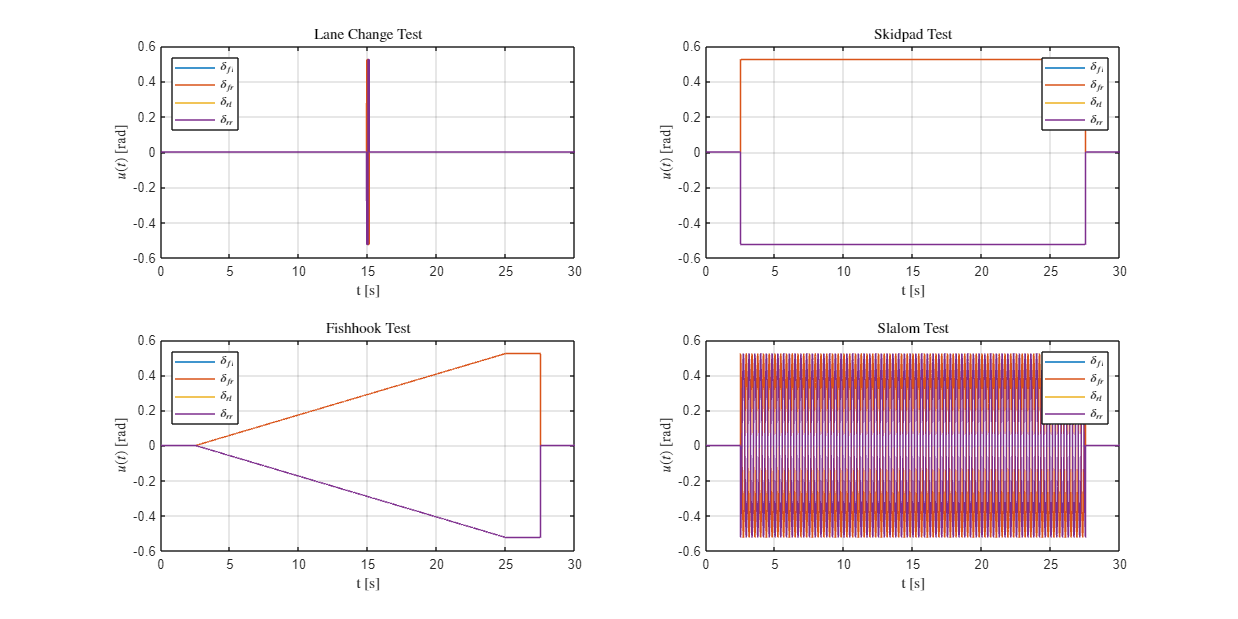

% Maneuver parameters

v = 0.2; % Vehicle velocity [m/s]

% Lane change test (impulse input)
u1_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(30)) ones(1,100)*(deg2rad(-30)) ones(1,14900)*(deg2rad(0))];
u2_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(30)) ones(1,100)*(deg2rad(-30)) ones(1,14900)*(deg2rad(0))];
u3_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(-30)) ones(1,100)*(deg2rad(30)) ones(1,14900)*(deg2rad(0))];
u4_lane_change = [ones(1,14900)*(deg2rad(0)) ones(1,100)*(deg2rad(-30)) ones(1,100)*(deg2rad(30)) ones(1,14900)*(deg2rad(0))];
u_lane_change = [u1_lane_change; u2_lane_change; u3_lane_change; u4_lane_change];

% Skidpad test (step input)
u1_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u2_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(30)) ones(1,2500)*(deg2rad(0))];
u3_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u4_skidpad = [ones(1,2500)*(deg2rad(0)) ones(1,25000)*(deg2rad(-30)) ones(1,2500)*(deg2rad(0))];
u_skidpad = [u1_skidpad; u2_skidpad; u3_skidpad; u4_skidpad];

% Fishhook test (ramp input)
angles = deg2rad(linspace(0,30,22500));
u1_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u2_fishhook = [ones(1,2500)*(deg2rad(0)) angles ones(1,2500)*deg2rad(30) ones(1,2500)*(deg2rad(0))];
u3_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u4_fishhook = [ones(1,2500)*(deg2rad(0)) -angles ones(1,2500)*deg2rad(-30) ones(1,2500)*(deg2rad(0))];
u_fishhook = [u1_fishhook; u2_fishhook; u3_fishhook; u4_fishhook];

% Slalom test (sine input)
n_cones = 60;
angles = linspace(0,2*n_cones*pi,25000);
u1_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u2_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u3_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u4_slalom = [ones(1,2500)*(deg2rad(0)) deg2rad(-30*cos(angles)) ones(1,2500)*(deg2rad(0))];
u_slalom = [u1_slalom; u2_slalom; u3_slalom; u4_slalom];

% Plot
t=1:30000;
fig = figure(); 
fig.Position(3:4) = [4000, 2000];
% Lane change (impulse)
subplot(2,2,1)
plot(t/1000,u1_lane_change)
hold on;
plot(t/1000,u2_lane_change)
plot(t/1000,u3_lane_change)
plot(t/1000,u4_lane_change)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Lane Change Test','Interpreter','latex')
grid on;
hold off;
% Skidpad (step)
subplot(2,2,2)
plot(t/1000,u1_skidpad)
hold on;
plot(t/1000,u2_skidpad)
plot(t/1000,u3_skidpad)
plot(t/1000,u4_skidpad)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Skidpad Test','Interpreter','latex')
grid on;
hold off;
% Fishhook (ramp)
subplot(2,2,3)
plot(t/1000,u1_fishhook)
hold on;
plot(t/1000,u2_fishhook)
plot(t/1000,u3_fishhook)
plot(t/1000,u4_fishhook)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northwest')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Fishhook Test','Interpreter','latex')
grid on;
hold off;
% Slalom (sine)
subplot(2,2,4)
plot(t/1000,u1_slalom)
hold on;
plot(t/1000,u2_slalom)
plot(t/1000,u3_slalom)
plot(t/1000,u4_slalom)
legend('$\delta_{fl}$','$\delta_{fr}$','$\delta_{rl}$','$\delta_{rr}$','Interpreter','latex','Location','northeast')
xlabel('t [s]','Interpreter','latex')
ylabel('$u(t)$ [rad]','Interpreter','latex')
title('Slalom Test','Interpreter','latex')
grid on;
hold off;

% Vehicle model

a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));

b11 = (u_fl*C_fl)/(m*v);
b12 = (u_fr*C_fr)/(m*v);
b13 = (u_rl*C_rl)/(m*v);
b14 = (u_rr*C_rr)/(m*v);
b21 = (l_f*u_fl*C_fl)/J;
b22 = (l_f*u_fr*C_fr)/J;
b23 = -(l_r*u_rl*C_rl)/J;
b24 = -(l_r*u_rr*C_rr)/J;

A = [a11 a12;
     a21 a22];

B = [b11 b12 b13 b14;
     b21 b22 b23 b24];

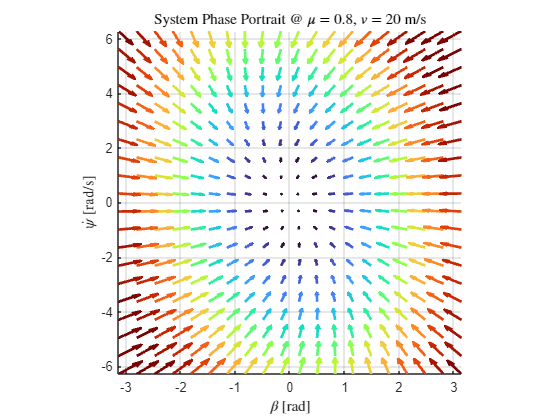

% System phase portrait

u_fl = 0.4; % Coefficient of friction for ground and FL tire interconnect
u_fr = 0.4; % Coefficient of friction for ground and FR tire interconnect
u_rl = 0.4; % Coefficient of friction for ground and RL tire interconnect
u_rr = 0.4; % Coefficient of friction for ground and RR tire interconnect
v = 0.2; % Vehicle velocity [m/s]

% Compute system matrix
a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
A = [a11 a12;
     a21 a22];

% Define a range of initial conditions
X1_range = linspace(-3.14159, 3.14159, 20);
X2_range = linspace(-6.28319, 6.28319, 20);

% Create a meshgrid of initial conditions
[X1, X2] = meshgrid(X1_range, X2_range);

% Initialize vectors to store the derivatives
X1_dot = zeros(size(X1));
X2_dot = zeros(size(X2));

% Calculate the derivatives for each initial condition
for i = 1:numel(X1)
    X_dot = A * [X1(i); X2(i)];
    X1_dot(i) = X_dot(1);
    X2_dot(i) = X_dot(2);
end
Z = (sqrt(X1_dot.^2 + X2_dot.^2));
Z = Z/max(Z,[],'all');
Z = reshape(Z.',1,[]);
[sortedZ, sortedIdx] = sort(Z);
sortedIdx = reshape(sortedIdx,[20,20]).';
X1_s = X1(sortedIdx);
X2_s = X2(sortedIdx);
X1_dot_s = X1_dot(sortedIdx);
X2_dot_s = X2_dot(sortedIdx);

% Plot
fig = figure(); 
fig.Position(3:4) = [560, 420];
cmap = turbo(size(X1_s,1)); 
hold on;
for i = 1:size(X1_s,1)
    quiver(X1_s(i,:),X2_s(i,:),X1_dot_s(i,:),X2_dot_s(i,:), .2, 'Color', cmap(i,:), 'LineWidth',2)
end
hold off;
xlabel('X1');
ylabel('X2');
xlabel('$\beta$ [rad]','Interpreter','latex');
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex');
title('System Phase Portrait @ $\mu = 0.8$, $v = 20$ m/s','Interpreter','latex');
grid on;
axis tight;
pbaspect([1 1 1])

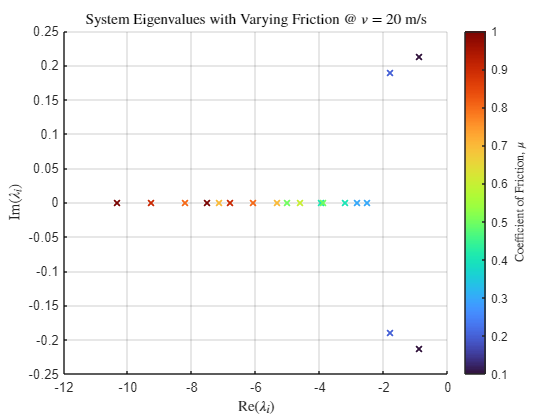

% System eignvalues with varying friction

EV = []; % Array to store system eigenvalues
v = 0.35; % Vehicle velocity [m/s]
for u=0.1:0.1:1
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
u=0.1:0.1:1;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],u,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],u,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Coefficient of Friction, $\mu$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Friction @ $v = 20$ m/s','Interpreter','latex');
grid on;

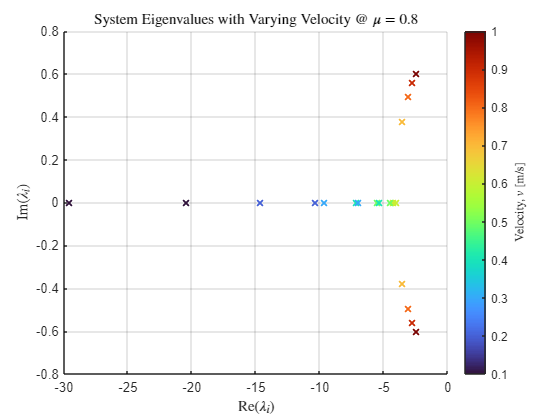

% System eignvalues with varying velocity

EV = []; % Array to store system eigenvalues
u = 0.8; % Coefficient of friction for ground and tire interconnect
for v=0.1:0.1:1
    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;
    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];
    % Compute eigenvalues
    EV(:,end+1) = eig(A);
end

% Plot
v=0.1:0.1:1;
fig = figure(); 
fig.Position(3:4) = [560, 420];
scatter(real(EV(1,:)),imag(EV(1,:)),[],v,'LineWidth',1.5,'Marker','x')
hold on;
scatter(real(EV(2,:)),imag(EV(2,:)),[],v,'LineWidth',1.5,'Marker','x')
cb = colorbar();
ylabel(cb,'Velocity, $v$ [m/s]','Interpreter','latex');
colormap turbo;
hold off;
xlabel('Re$(\lambda_i)$','Interpreter','latex');
ylabel('Im$(\lambda_i)$','Interpreter','latex');
title('System Eigenvalues with Varying Velocity @ $\mu = 0.8$','Interpreter','latex');
grid on;

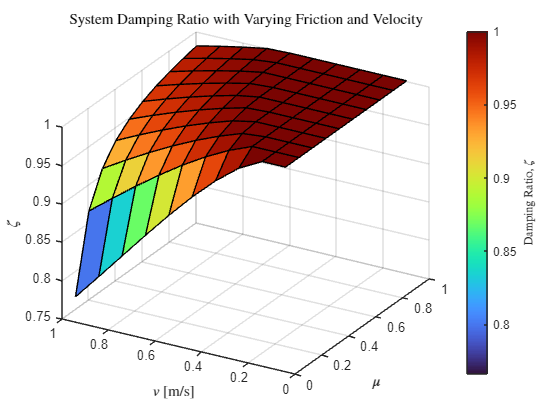

% System damping ratio with varying friction and velocity

zeta = []; % Array to store system eigenvalues
for u=0.1:0.1:1
    for v=0.1:0.1:1
        % Set friction value
        u_fl = u;
        u_fr = u;
        u_rl = u;
        u_rr = u;
        % Update system matrix
        a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
        a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
        a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
        a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
        A = [a11 a12;
             a21 a22];
        % Compute damping ratio
        EV = eig(A);
        zeta(:,end+1) = -real(EV)./abs(EV);
    end
end

% Plot
u=0.1:0.1:1;
v=0.1:0.1:1;
[X,Y] = meshgrid(u,v);
Z = reshape(zeta(1, :), 10, 10);
fig = figure(); 
fig.Position(3:4) = [560, 420];
s = surf(X,Y,Z,'FaceAlpha',1.0);
hold on;
cb = colorbar();
ylabel(cb,'Damping Ratio, $\zeta$','Interpreter','latex');
colormap turbo;
hold off;
xlabel('$\mu$','Interpreter','latex');
ylabel('$v$ [m/s]','Interpreter','latex');
zlabel('$\zeta$','Interpreter','latex');
title('System Damping Ratio with Varying Friction and Velocity','Interpreter','latex');
grid on;
view([-60 30]);

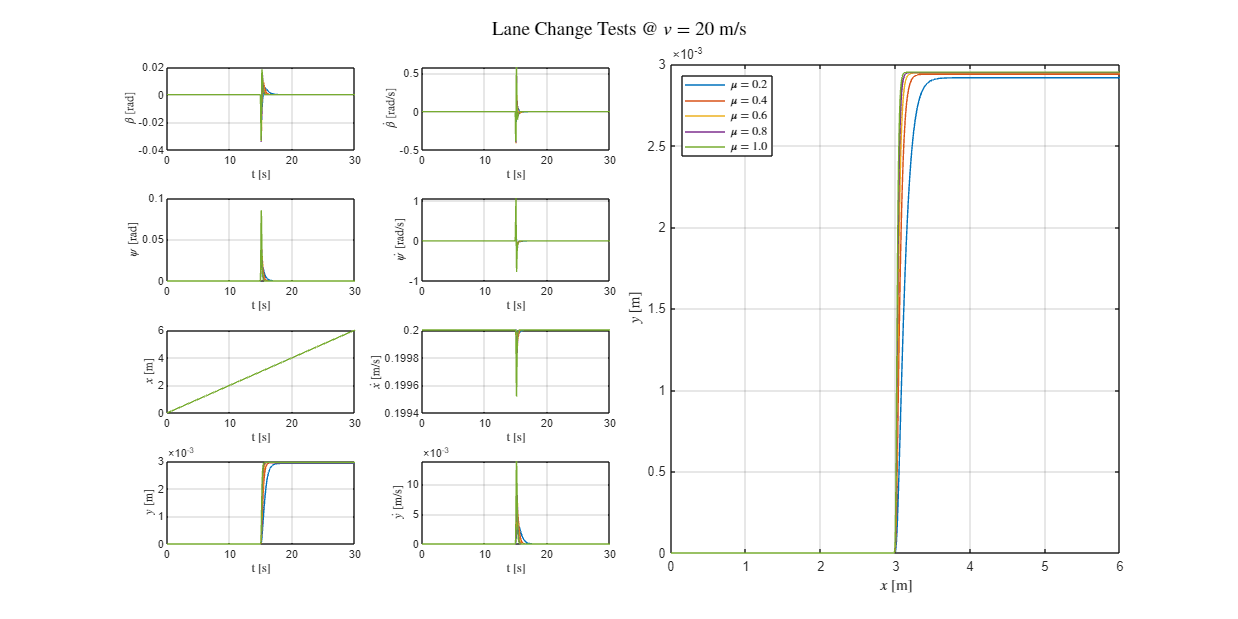

% Simulate lane change tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.2; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
     b21 b22 b23 b24];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t)+B*u_lane_change(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t)+Beta(t));
        Vy(t) = v*sin(Psi(t)+Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
% xlim([0,600])
% ylim([-0.1,1.5])
% pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Lane Change Tests @ $v = 20$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

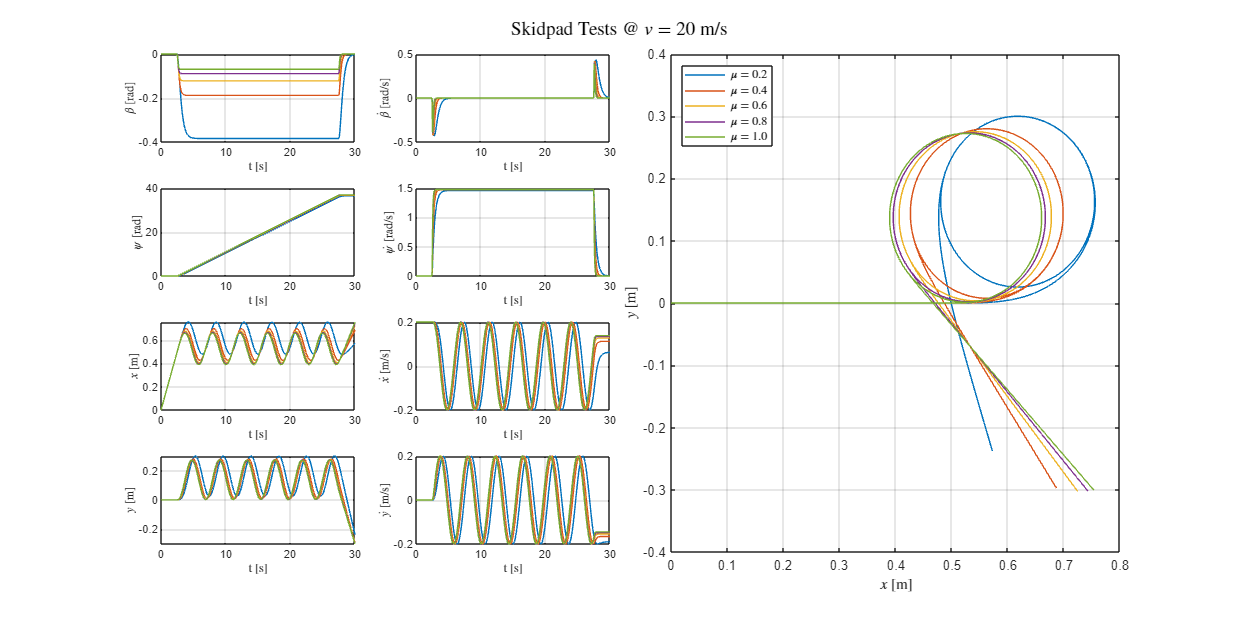

% Simulate skidpad tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.2; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
     b21 b22 b23 b24];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t)+B*u_skidpad(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t)+Beta(t));
        Vy(t) = v*sin(Psi(t)+Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
% xlim([0,100])
% ylim([-50,50])
% pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Skidpad Tests @ $v = 20$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

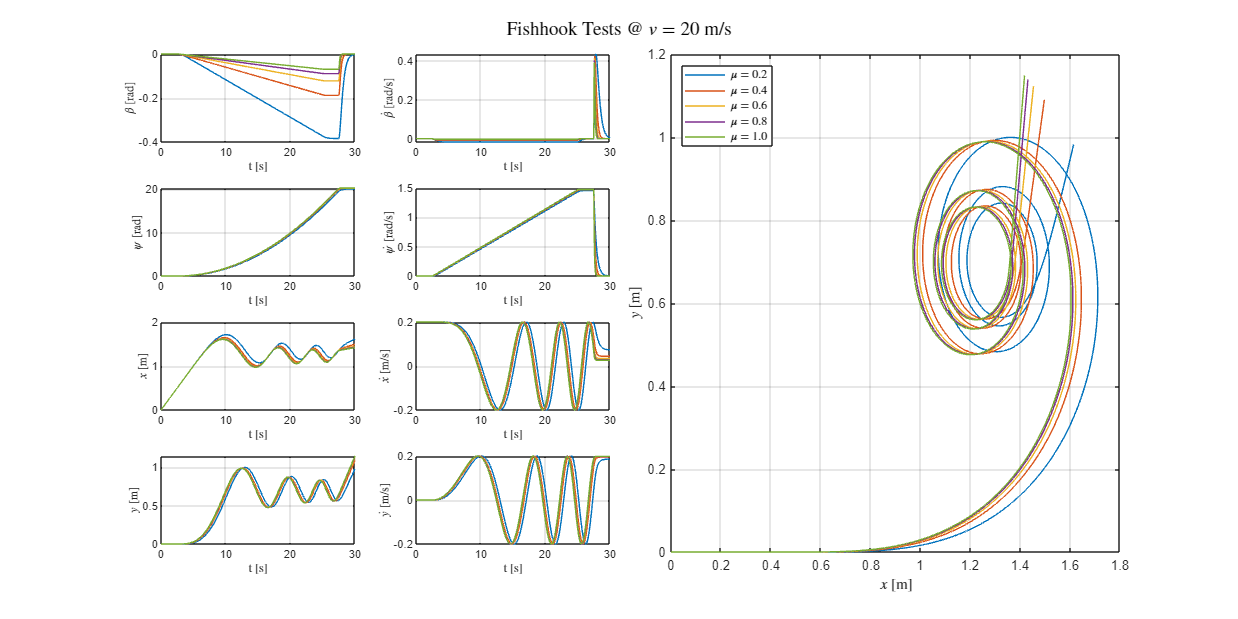

% Simulate fishhook tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.2; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
     b21 b22 b23 b24];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t)+B*u_fishhook(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t)+Beta(t));
        Vy(t) = v*sin(Psi(t)+Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
% xlim([0,150])
% ylim([-50,100])
% pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Fishhook Tests @ $v = 20$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

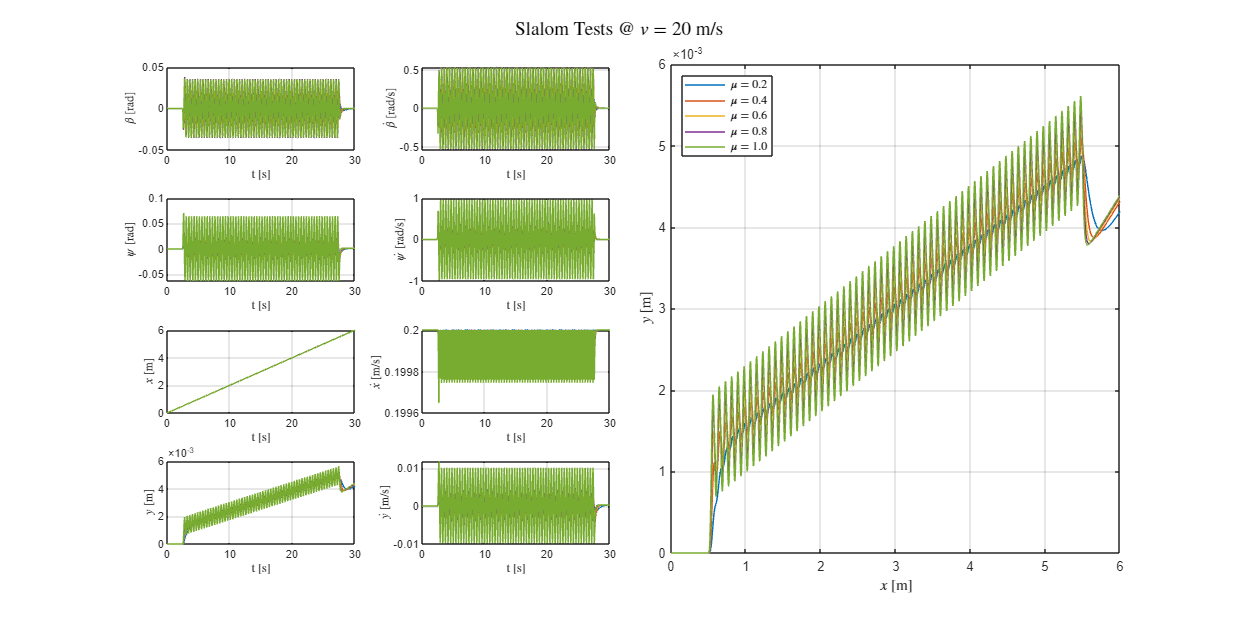

% Simulate slalom tests with varying friction

BETA = [];
BETA_DOT = [];
PSI = [];
PSI_DOT = [];
PX = [];
VX = [];
PY = [];
VY = [];

for u=0.2:0.2:1

    % Initialization
    dt = 0.001; % Simulation timestep [s]
    v = 0.2; % Vehicle velocity [m/s]
    X = [];
    X(:,1) = [0;0];
    X_dot = [];
    Psi = [];
    Psi(1) = 0;
    Beta = [];
    Vx = [];
    Vy = [];
    Px = [];
    Px(1) = 0;
    Py = [];
    Py(1) = 0;

    % Set friction value
    u_fl = u;
    u_fr = u;
    u_rl = u;
    u_rr = u;

    % Update system matrix
    a11 = -(1/(m*v)) * (u_fl*C_fl+u_fr*C_fr+u_rl*C_rl+u_rr*C_rr);
    a12 = ((1/(m*v^2)) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr))) - 1;
    a21 = (1/J) * (l_r*(u_rl*C_rl+u_rr*C_rr) - l_f*(u_fl*C_fl+u_fr*C_fr));
    a22 = -(1/(J*v)) * (l_f^2*(u_fl*C_fl+u_fr*C_fr) + l_r^2*(u_rl*C_rl+u_rr*C_rr));
    A = [a11 a12;
         a21 a22];

    % Update input matrix
    b11 = (u_fl*C_fl)/(m*v);
    b12 = (u_fr*C_fr)/(m*v);
    b13 = (u_rl*C_rl)/(m*v);
    b14 = (u_rr*C_rr)/(m*v);
    b21 = (l_f*u_fl*C_fl)/J;
    b22 = (l_f*u_fr*C_fr)/J;
    b23 = -(l_r*u_rl*C_rl)/J;
    b24 = -(l_r*u_rr*C_rr)/J;
    B = [b11 b12 b13 b14;
     b21 b22 b23 b24];
    
    % Simulation at each millisecond
    for t=1:30000
        X_dot(:,t) = A*X(:,t)+B*u_slalom(:,t);
        X(:,t+1) = X(:,t) + X_dot(:,t)*dt;
        Beta(t) = X(1,t);
        Psi(t+1) = Psi(t) + X(2,t)*dt;
        Vx(t) = v*cos(Psi(t)+Beta(t));
        Vy(t) = v*sin(Psi(t)+Beta(t));
        Px(t+1) = Px(t) + Vx(t)*dt;
        Py(t+1) = Py(t) + Vy(t)*dt;
    end
    BETA(end+1,:) = Beta;
    BETA_DOT(end+1,:) = X_dot(1,:);
    PSI(end+1,:) = Psi;
    PSI_DOT(end+1,:) = X(2,:);
    PX(end+1,:) = Px;
    VX(end+1,:) = Vx;
    PY(end+1,:) = Py;
    VY(end+1,:) = Vy;
end

% Plot
t=1:30000;
u=0.2:0.2:1;
fig = figure(); 
fig.Position(3:4) = [1500, 750];
% Plot states
subplot(4,4,1)
plot(t/1000,BETA(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\beta$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,2)
plot(t/1000,BETA_DOT(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\beta}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,5)
plot(t/1000,PSI(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\psi$ [rad]','Interpreter','latex')
grid('on')
subplot(4,4,6)
plot(t/1000,PSI_DOT(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{\psi}$ [rad/s]','Interpreter','latex')
grid('on')
subplot(4,4,9)
plot(t/1000,PX(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$x$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,10)
plot(t/1000,VX(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid('on')
subplot(4,4,13)
plot(t/1000,PY(:,1:end-1)')
xlabel('t [s]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
grid('on')
subplot(4,4,14)
plot(t/1000,VY(:,1:end)')
xlabel('t [s]','Interpreter','latex')
ylabel('$\dot{y}$ [m/s]','Interpreter','latex')
grid('on')
% Plot trajectory
subplot(4,4,[3,4,7,8,11,12,15,16])
plot(PX(:,1:end-1)',PY(:,1:end-1)')
xlabel('$x$ [m]','Interpreter','latex')
ylabel('$y$ [m]','Interpreter','latex')
% xlim([0,600])
% ylim([-0.5,2.5])
% pbaspect([1 1 1])
grid('on')
% Common title and legend
sgtitle('Slalom Tests @ $v = 20$ m/s','Interpreter','latex')
legend('$\mu = 0.2$','$\mu = 0.4$','$\mu = 0.6$','$\mu = 0.8$','$\mu = 1.0$', ...
       'Interpreter','latex','Location','northwest')

% Environment parameters
rho = 1.225; % kg/m^3
u_fl = 0.1;
u_fr = 0.1;
u_rl = 0.1;
u_rr = 0.1;

% Vehicle parameters
m = 1630; % kg
J = 3853; % kg-m^2
l_f = 1.2313; % m
l_r = 1.4087; % m
C_d = 0.32; % unitless
A = 1.8729; % m^2
R = 0.34; % m
C = 50000; % N/rad
V = 5; % m/s

% Vehicle model
a11 = -(C/(m*V)) * (u_fl+u_fr+u_rl+u_rr);
a12 = (C/(m*V^2)) * ((-m*V^2/C) + l_r*(u_rl+u_rr) - l_f*(u_fl+u_fr));
a21 = (C/J) * (l_r*(u_rl+u_rr) - l_f*(u_fl+u_fr));
a22 = -(C/(J*V)) * (l_f^2*(u_fl+u_fr) + l_r^2*(u_rl+u_rr));

b11 = (C/(m*V)) * (u_fl+u_fr);
b12 = (C/(m*V)) * (u_rl+u_rr);
b21 = ((C*l_f)/J) * (u_fl+u_fr);
b22 = (-(C*l_r)/J) * (u_rl+u_rr);

d1 = (1/(2*m*V)) * (rho*A*C_d);
d2 = (1/(2*J)) * (rho*A*C_d*(l_f-l_r));


Ap = [a11 a12;
      a21 a22];

Bp = [b11 b12;
      b21 b22];

Dp = [d1;
      d2];

Cp = [1 0;
      0 1];

By = [0 0;
      0 0];

Dy = [0;
      0];

Mp = [1 0;
      0 1];

Dz = [0;
      0];

% Lumped system matrices
A = Ap;
B = [Dp Bp];
C = [Cp; Mp];
D = [Dy By; Dz zeros(size(Dz,1), size(By,2))];

% State-space system
Sol = ss(A, B, C, D)

Sol =
 
  A = 
            x1       x2
   x1   -2.454  -0.9565
   x2   0.4604   -1.817
 
  B = 
              u1         u2         u3
   x1  4.504e-05      1.227      1.227
   x2  -1.69e-05      3.196     -3.656
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
   y3   1   0
   y4   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
   y3   0   0   0
   y4   0   0   0
 
Continuous-time state-space model.


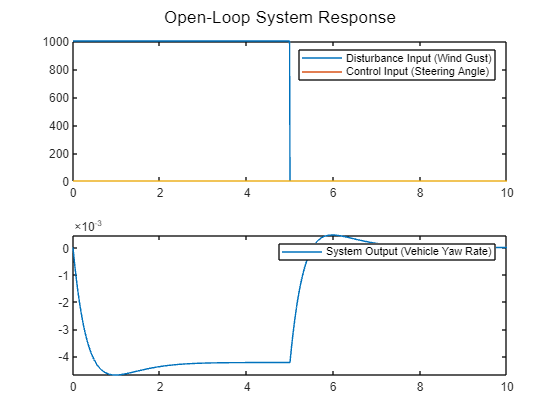

% Define the lumped (disturbance + control) input
t = 0:0.01:10;
w_amplitude = 1000;
w_duration = 5;
w_step = w_amplitude * (t >= 0 & t < w_duration);
u = zeros(size(Bp,2), size(w_step,2));
w = [w_step; u];

% Simulate the open-loop system response
[y_ol, t_out, x_ol] = lsim(Sol, w, t);

% Plot the results
figure;
sgtitle('Open-Loop System Response');
subplot(2, 1, 1);
plot(t, w);
legend('Disturbance Input (Wind Gust)', 'Control Input (Steering Angle)');
subplot(2, 1, 2);
plot(t, y_ol(:, 2));
legend('System Output (Vehicle Yaw Rate)');

S = ltisys(A, B, C, D);
nz = size(Mp, 1);
nu = size(Bp, 2);
r = [nz nu];
[gopt, G] = hinflmi(S, r)


 Minimization of gamma:

 Solver for linear objective minimization under LMI constraints 

 Iterations   :    Best objective value so far 
 
     1                   0.021865
     2               3.987974e-03
     3               3.987974e-03
     4               2.961871e-04
     5               2.961871e-04
     6               4.532247e-06
     7               4.532247e-06
     8               4.532247e-06
     9               4.532247e-06
    10               1.725859e-06
    11               1.725859e-06
    12               9.655074e-07
***                 new lower bound: -1.205174e-06
    13               1.599889e-07
***                 new lower bound: -4.304051e-08
    14               5.936835e-09
***                 new lower bound: -1.634747e-10
    15               5.936835e-09
    16               5.936835e-09
***                 new lower bound: 1.831822e-09
    17               4.112500e-09
***                 new lower bound: 3.329733e-09
    18               4.0555

gopt = 4.6709e-12

G = 1.0e+10 *

   -4.6414   -2.5474         0
   -4.1119    2.7111         0
         0         0      -Inf


% H∞ controller matrices
disp('H∞ controller:')

H∞ controller:


[Ac, Bc, Cc, Dc] = ltiss(G)


Ac =

     []


Bc =

  0×2 empty double matrix


Cc =

  2×0 empty double matrix



Dc = 1.0e+10 *

   -4.6414   -2.5474
   -4.1119    2.7111


% Closed-loop system matrices
disp('Closed-loop system:')

Closed-loop system:


Acl = [Ap+Bp*Dc*Mp, Bp*Cc; Bc*Mp, Ac]

Acl = 1.0e+11 *

   -1.0740    0.0201
    0.0201   -1.8053


Bcl = [Dp+Bp*Dc*Dz; Bc*Dz]

Bcl = 1.0e-04 *

    0.4504
   -0.1690


Ccl = [Cp+By*Dc*Mp, By*Cc]

Ccl =      1     0
     0     1


Dcl = Dy+By*Dc*Dz

Dcl =      0
     0



% Closed-loop system
Scl = ss(Acl, Bcl, Ccl, Dcl);

% Verification of designed H∞ controller
disp('H∞ norm:')

H∞ norm:


hinf_norm = hinfnorm(Scl)

hinf_norm = 4.2708e-16

disp('Closed-loop poles:')

Closed-loop poles:


eig_Acl = eig(Acl)

eig_Acl = 1.0e+11 *

   -1.0735
   -1.8058


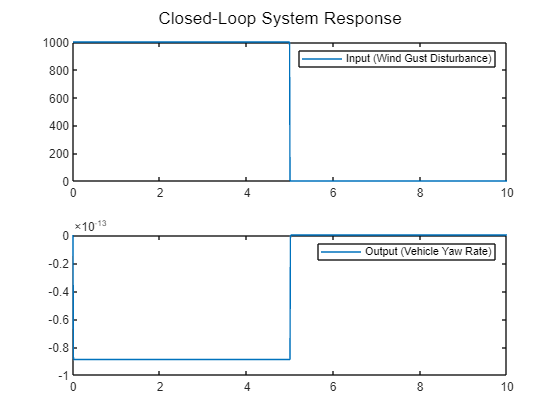

% Define the disturbance input
t = 0:0.01:10;
w_amplitude = 1000;
w_duration = 5;
w_step = w_amplitude * (t >= 0 & t < w_duration);
w = w_step;

% Simulate the closed-loop system response
[y_cl, t_out, x_cl] = lsim(Scl, w', t);

% Plot the results
figure;
sgtitle('Closed-Loop System Response');
subplot(2, 1, 1);
plot(t, w);
legend('Input (Wind Gust Disturbance)');
subplot(2, 1, 2);
plot(t, y_cl(:, 2));
legend('Output (Vehicle Yaw Rate)');